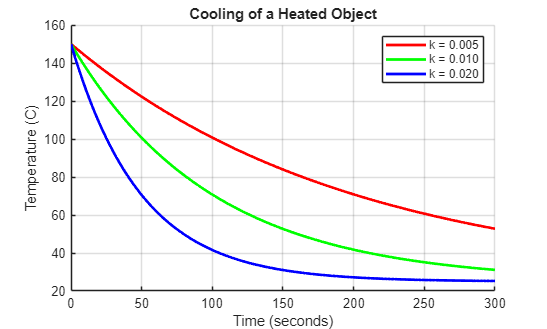

% Author: Christopher Bourjaili
% Module 2
% Project 8
% Title: Cooling of a Heated Object
%
% Summary of Code:
% - Simulates temperature decay of a heated object over time.
% - Uses a simplified heat transfer cooling model.
% - Compares multiple cooling coefficients.
% - Tracks object temperature at each time step.
% - Creates temperature vs time plots.
% - Demonstrates how cooling rate changes with conditions.
%
% What I Learned:
% This project demonstrated how MATLAB can model heat transfer processes
% using loops, arrays, and time-stepped calculations. I learned that
% larger cooling coefficients cause the object to lose heat faster,
% meaning stronger airflow or better heat transfer lowers temperature
% more quickly. I also practiced visualizing exponential-style decay
% behavior through engineering graphs.

clc
clear
close all

T_initial = 150;           
T_env = 25;                 

dt = 1;                     
t_max = 300;               

t = 0:dt:t_max;
n = length(t);

k = [0.005 0.01 0.02];

colors = ['r','g','b'];

figure
hold on
grid on

for j = 1:length(k)
    
    T = zeros(1,n);
    T(1) = T_initial;
    
    for i = 2:n

        dT = -k(j) * (T(i-1) - T_env);

        T(i) = T(i-1) + dT*dt;
        
    end

    plot(t, T, colors(j), 'LineWidth',2)
    
end

xlabel('Time (seconds)')
ylabel('Temperature (C)')
title('Cooling of a Heated Object')
legend('k = 0.005','k = 0.010','k = 0.020')


disp('Physical Interpretation:')

Physical Interpretation:


disp('1. Temperature drops quickly at first when very hot.')

1. Temperature drops quickly at first when very hot.


disp('2. Cooling slows as object nears room temperature.')

2. Cooling slows as object nears room temperature.


disp('3. Larger cooling coefficients increase heat loss rate.')

3. Larger cooling coefficients increase heat loss rate.


disp('4. Airflow or better conduction can increase cooling speed.')

4. Airflow or better conduction can increase cooling speed.
